%% Generate some synthetic data
number_of_seqences = 1;
T = 300; % length of data to generate
Nneurons = 10*ones(number_of_seqences,1); % number of neurons in each sequencestate_action
Dt = 3.*ones(number_of_seqences,1); % gap between each member of the sequence
NeuronNoise = 0.001; % probability of added noise in each bin
SeqNoiseTime = zeros(number_of_seqences,1); % Jitter parameter = 0%
SeqNoiseNeuron = 1.*ones(number_of_seqences,1); % Participation parameter = 100%
X = generate_data(T,Nneurons,Dt,NeuronNoise,SeqNoiseTime,SeqNoiseNeuron,0,0,0,0,0);



figure(1)
imagesc(state_action)

## Seq_NMF on color 

one_hot_encode = false;
use_action = true;

if one_hot_encode
    num_labels = 3;
    one_hot_encoded = zeros(num_labels, T); % Initialize the one-hot encoded matrix
    
    for i = 1:T
        one_hot_encoded(state(i), i) = 1; % Set the corresponding element to 1
    end

    state_onehot = one_hot_encoded;
    X = double(state_onehot);
elseif use_action
    X = double([state_onehot; action_onehot]);
else
    X = double(state_onehot);
end

state_dim = 3;
seed=1;
%% Fit with seqNMF
K = 2;
L = 10;
T = length(state);
lambda =.00;
lambdaH = 0.01; % Encourage event-based
lambdaL1H = 0.01;
lambdaW = 0.0;
lambdabin = 0.01;
shg; clf
for seed=2
rng(seed)
[W,H] = seqNMF(X,'K',K, 'L', L,'lambda', lambda,'lambdaOrthoH', lambdaH, 'lambdaL1H', ...
                lambdaL1H, 'lambdaOrthoW', lambdaW, "lambdabin", lambdabin, 'maxiter', 301, ...
                'W_init', 0, 'H_init', 0);
%[W,H] = seqNMF(X,'K',K, 'L', L,'lambda', lambda,'lambdaOrthoH', lambdaH)
%% Look at factors
% figure; SimpleWHPlot(W,H); title('SeqNMF reconstruction')
% figure; SimpleWHPlot(W,H,X); title('SeqNMF factors, with raw data')

H_bin  = H;
thresh = 0.5;
H_bin(H_bin > thresh) = 1;
H_bin(H_bin < thresh) = 0;
plot_option = 1;
C = helper.reconstruct_option(W,H_bin, plot_option, 101)

save(strcat('C_est_color_', num2str(L), '_seed', num2str(seed), '.mat'),'C');
end

### Evaluation

%get_c_seq = c_seq(1:10:end);
[value,argmax]=max(H,[],1);
argmax = argmax .* (value > (min(value) + max(value))/2);
non_zero_c_est = nonzeros(argmax)';

% calculate precision and recall
true_boundary_color = zeros(1, T);
true_boundary_color(1:10:end) = 1; % set every 3 elemets as boundary

precision = nnz(argmax .* true_boundary_color) / nnz(argmax)
recall = nnz(argmax .* true_boundary_color) / nnz(true_boundary_color)
f1 = 2 / (1 / precision + 1 / recall)

## Seq_NMF on driving

traj_len = 120

traj_len = 120

state_dim = 4;
X = double([state_normed(1:4,:); action_normed]);
action_normed = abs(action_normed);
% X = double([state_normed(1:2,1:240); action_normed(:,1:240)]);

%% Fit with seqNMF
K = 5;
L = 40;
[dim, len] = size(X)

dim = 6

len = 2245

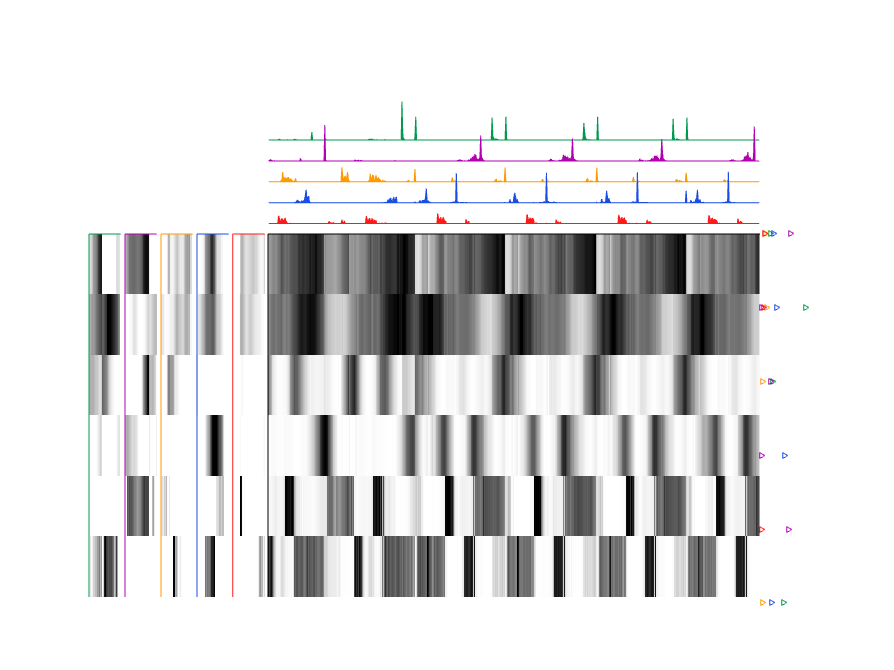

seed = 59

rand_id_traj = 17

rand_id_subtraj = 1

rand_id_traj = 16

rand_id_subtraj = 1

ans = 0.9958

rand_id_traj = 11

rand_id_subtraj = 1

ans = 0.7681

ans = 0.8726

rand_id_traj = 5

rand_id_subtraj = 2

ans = 0.8000

ans = 0.7752

ans = 0.7653

rand_id_traj = 4

rand_id_subtraj = 2

ans = 0.7251

ans = 0.6655

ans = 0.5977

ans = 0.6384

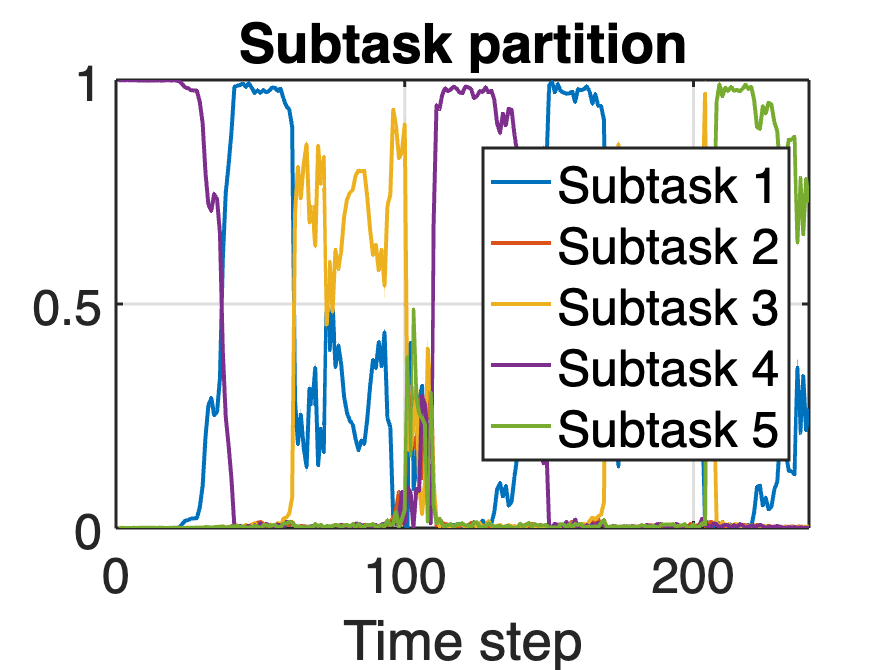

lambda =.00;
lambdaH = 0.001; % Encourage event-based
lambdaL1H = 0.01;
lambdaW = 0.0;
lambdabin = 0.01;
shg; clf
% for lambdaH = param_list
%      for lambdaL1H = param_list
%          for lambdabin = param_list
for seed = 59
seed
rng(seed)
[W,H] = seqNMF(X, traj_len, 'K',K, 'L', L,'lambda', lambda,'lambdaOrthoH', lambdaH, 'lambdaL1H', ...
                lambdaL1H, 'lambdaOrthoW', lambdaW, "lambdabin", lambdabin, 'maxiter', 301, ...
                                'shift', 1, 'seed', seed,...
                                'W_init', 2, 'H_init', nan, 'showPlot', 1, 'savePlot', 1, 'start_indices', start_indices);

% Create a figure and divide it into a 2x2 grid of subplots
% figure;
% 
% for k = 1:K
% % Plot the first subplot
%     subplot(2, 3, k);
%     plot(squeeze(W(1, k, :)) * 60, squeeze(W(2, k, :)) * 20);
%     title(strcat('Subplot pattern ', num2str(k)));
%     xlim([0, 60]);
%     ylim([0, 20]);
% end
H_bin  = H;
thresh = 0.5;
H_bin(H_bin > thresh) = 1;
H_bin(H_bin < thresh) = 0;
plot_option = 1;
C = helper.reconstruct_option(W,H_bin, plot_option, 210);

saveas(gcf,sprintf('train_logs/seed%d/data_length_%d/OrthoH_%.3f_H1_%.3f_Hbin_%.3f_option.png', seed, length(X),  lambdaH, lambdaL1H, lambdabin)); 

str = sprintf('train_logs/seed%d/data_length_%d/OrthoH_%.3f_H1_%.3f_Hbin_%.3f_C.mat', seed, length(X), lambdaH, lambdaL1H, lambdabin);
save(str, 'C')
str = sprintf('train_logs/seed%d/data_length_%d/OrthoH_%.3f_H1_%.3f_Hbin_%.3f_W.mat', seed, length(X), lambdaH, lambdaL1H, lambdabin);
save(str, 'W')
str = sprintf('train_logs/seed%d/data_length_%d/OrthoH_%.3f_H1_%.3f_Hbin_%.3f_H.mat', seed, length(X), lambdaH, lambdaL1H, lambdabin);
save(str, 'H')
% end
% end
% end
end

helper.visualize_new_traj(X, W, H, traj_len, L, K, state_dim);
save('subtask_pattern.mat', 'W');

## Kitchen

traj_len = 230

traj_len = 230

X = double(s_a_pairs_normed);

losses = [];
%% Fit with seqNMF
K = 5;
L = 100;
[dim, len] = size(X)

dim = 18

len = 4639

lambda =.00;
lambdaW = 0.00;
param_list = [0.001,  0.01,  0.05, 0.1]

param_list =     0.0010    0.0100    0.0500    0.1000


% param_list = [0.001]
seeds = 77:100

seeds =     77    78    79    80    81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100


lambdaH = 0.001; % Encourage event-based
lambdaL1H = 0.01;
lambdabin = 0.01;
seed = 76;
for seed = seeds
    seed
% for lambdaH = param_list
%     for lambdaL1H = param_list
%         for lambdabin = param_list
shg; clf
disp('Running seqNMF on Kitchen data (9 dim states + 9 dim actions)')
rng(seed)
[W,H, cost,loadings,power] = seqNMF(X, traj_len, 'K',K, 'L', L,'lambda', lambda,'lambdaOrthoH', lambdaH, ...
                'lambdaL1H', lambdaL1H, 'lambdaOrthoW', lambdaW, ...
                'lambdaL1W', 0, "lambdabin", lambdabin,...
                'maxiter', 400, 'reward', rewards, ...
                'start_indices', traj_start_index, 'shift', 1, 'seed', seed, ...
                'W_init', 3, 'H_init', nan, 'showPlot', 1, 'savePlot', 1);
loss = cost(end)

%% Look at factors
% figure; SimpleWHPlot(W,H); title('SeqNMF reconstruction')
% figure; SimpleWHPlot(W,H,X); title('SeqNMF factors, with raw data')



vis_start = traj_start_index(1);
vis_end = traj_start_index(2)-2;

% Create a figure and divide it into a 2x2 grid of subplots
figure;

for k = 1:K
% Plot the first subplot
    subplot(3, 2, k);
    plot(1:vis_end-vis_start+1, squeeze(H(k, vis_start:vis_end)));
    title(strcat('Subplot coeff ', num2str(k)));
    ylim([0, 1]);
end
saveas(gcf,sprintf('train_logs/seed%d/data_length_%d/OrthoH_%.3f_H1_%.3f_Hbin_%.3f_coeff.png', seed, length(X),  lambdaH, lambdaL1H, lambdabin)); 
      

H_bin  = H;
thresh = 0.5;
H_bin(H_bin > thresh) = 1;
H_bin(H_bin < thresh) = 0;
plot_option = 1;
C = helper.reconstruct_option(W,H_bin, plot_option, 410);
saveas(gcf,sprintf('train_logs/seed%d/data_length_%d/OrthoH_%.3f_H1_%.3f_Hbin_%.3f_option.png', seed, length(X),  lambdaH, lambdaL1H, lambdabin)); 

losses = [losses, loss];
%         end
%     end
% end
end

seed = 77

Running seqNMF on Kitchen data (9 dim states + 9 dim actions)


rand_id_traj = 8

rand_id_subtraj = 2

rand_id_traj = 4

rand_id_subtraj = 3

rand_id_traj = 3

rand_id_subtraj = 2

rand_id_traj = 2

rand_id_subtraj = 1

rand_id_traj = 7

rand_id_subtraj = 2

ans = ans(:,:,1) =

    0.3965    0.3964    0.4002    0.3968    0.3887    0.3870    0.3832    0.3861    0.3859    0.3823    0.3855    0.3836    0.3861    0.3910    0.3921    0.3961    0.3979    0.4001    0.4120    0.4200    0.4288    0.4359    0.4429    0.4535    0.4561    0.4597    0.4656    0.4641    0.4601    0.4435    0.4318    0.4157    0.3936    0.3710    0.3507    0.3327    0.3149    0.2979    0.2868    0.2718    0.2589    0.2472    0.2359    0.2233    0.2139    0.1969    0.1733    0.1548    0.1313    0.1110    0.9790    0.9817    0.9807    0.9764    0.9786    0.9759    0.9754    0.9692    0.9588    0.9527    0.9315    0.9173    0.8965    0.8776    0.8555    0.8302    0.8045    0.7772    0.7551    0.7306    0.7039    0.6760    0.6552    0.6304    0.6023    0.5775    0.5554    0.5349    0.5148    0.4885    0.4687    0.4526    0.4376    0.4324    0.4239    0.4267    0.4295    0.4356    0.4512    0.4682    0.4856    0.4991    0.5247    0.5436    0.5704    0.5918    0.6099    0.6284

loss = 0.0923

seed = 78

Running seqNMF on Kitchen data (9 dim states + 9 dim actions)


rand_id_traj = 11

rand_id_subtraj = 3

rand_id_traj = 8

rand_id_subtraj = 1

rand_id_traj = 12

rand_id_subtraj = 3

rand_id_traj = 1

rand_id_subtraj = 1

rand_id_traj = 13

rand_id_subtraj = 2

ans = ans(:,:,1) =

    0.9601    0.9578    0.9551    0.9504    0.9476    0.9414    0.9324    0.9290    0.9156    0.9076    0.8923    0.8705    0.8520    0.8228    0.8025    0.7788    0.7544    0.7296    0.7043    0.6783    0.6560    0.6340    0.6112    0.5955    0.5726    0.5540    0.5419    0.5313    0.5203    0.5053    0.4914    0.4760    0.4625    0.4461    0.4316    0.4236    0.4136    0.4163    0.4178    0.4330    0.4488    0.4694    0.4921    0.5137    0.5356    0.5616    0.5838    0.6010    0.6269    0.6392    0.6530    0.6655    0.6760    0.6886    0.7002    0.7077    0.7185    0.7261    0.7385    0.7599    0.7752    0.8032    0.8271    0.8465    0.8679    0.8923    0.9042    0.9205    0.9278    0.9362    0.9437    0.9435    0.9351    0.9295    0.9206    0.9105    0.8931    0.8802    0.8599    0.8331    0.8127    0.7830    0.7634    0.7377    0.7088    0.6852    0.6574    0.6336    0.6135    0.5889    0.5603    0.5394    0.5131    0.4923    0.4701    0.4578    0.4424    0.4331

loss = 0.0972

seed = 79

Running seqNMF on Kitchen data (9 dim states + 9 dim actions)


rand_id_traj = 11

rand_id_subtraj = 1

rand_id_traj = 10

rand_id_subtraj = 4

rand_id_traj = 1

rand_id_subtraj = 2

rand_id_traj = 19

rand_id_subtraj = 2

rand_id_traj = 4

rand_id_subtraj = 4

ans = ans(:,:,1) =

    0.2835    0.2725    0.2626    0.2528    0.2517    0.2437    0.2391    0.2283    0.2233    0.2113    0.2040    0.1912    0.1854    0.1706    0.1640    0.1485    0.1359    0.1242    0.1153    0.1068    0.0920    0.0848    0.0765    0.0709    0.0599    0.0560    0.0552    0.0559    0.0517    0.0536    0.0576    0.0638    0.0725    0.0877    0.1053    0.1286    0.1529    0.1777    0.2064    0.2282    0.2517    0.2760    0.3029    0.3274    0.3566    0.3763    0.4003    0.4255    0.4531    0.4768    0.5010    0.5169    0.5315    0.5345    0.5332    0.5329    0.5215    0.5123    0.5025    0.4936    0.4803    0.4676    0.4510    0.4320    0.4139    0.3992    0.3783    0.3680    0.3455    0.3354    0.3249    0.3107    0.3020    0.2987    0.2927    0.2945    0.2935    0.2934    0.2945    0.3072    0.3119    0.3180    0.3240    0.3308    0.3382    0.3471    0.3610    0.3709    0.3889    0.4066    0.4220    0.4325    0.4485    0.4555    0.4719    0.4806    0.4868    0.4843

loss = 0.0852

seed = 80

Running seqNMF on Kitchen data (9 dim states + 9 dim actions)


rand_id_traj = 4

rand_id_subtraj = 3

rand_id_traj = 6

rand_id_subtraj = 1

rand_id_traj = 9

rand_id_subtraj = 4

rand_id_traj = 11

rand_id_subtraj = 2

rand_id_traj = 3

rand_id_subtraj = 4

ans = ans(:,:,1) =

    0.9566    0.9566    0.9490    0.9498    0.9441    0.9383    0.9348    0.9319    0.9201    0.9110    0.8963    0.8792    0.8582    0.8367    0.8151    0.7919    0.7623    0.7440    0.7186    0.6931    0.6720    0.6483    0.6204    0.6004    0.5821    0.5609    0.5383    0.5160    0.5010    0.4768    0.4586    0.4381    0.4264    0.4117    0.4051    0.4084    0.4121    0.4245    0.4361    0.4560    0.4775    0.4984    0.5210    0.5396    0.5617    0.5862    0.6097    0.6241    0.6412    0.6519    0.6658    0.6734    0.6870    0.6949    0.7105    0.7369    0.7550    0.7823    0.8031    0.8258    0.8540    0.8750    0.8924    0.9045    0.9167    0.9219    0.9264    0.9301    0.9278    0.9175    0.9026    0.8855    0.8710    0.8522    0.8417    0.8294    0.8209    0.8092    0.8052    0.7995    0.7906    0.7894    0.7806    0.7811    0.7806    0.7845    0.7914    0.7978    0.8083    0.8154    0.8217    0.8465    0.8767    0.8967    0.9205    0.9344    0.9360    0.9337

loss = 0.0879

seed = 81

Running seqNMF on Kitchen data (9 dim states + 9 dim actions)


rand_id_traj = 17

rand_id_subtraj = 1

rand_id_traj = 3

rand_id_subtraj = 4

rand_id_traj = 14

rand_id_subtraj = 2

rand_id_traj = 4

rand_id_subtraj = 2

rand_id_traj = 9

rand_id_subtraj = 3

ans = ans(:,:,1) =

    0.4018    0.3883    0.3749    0.3610    0.3502    0.3401    0.3270    0.3159    0.3073    0.2969    0.2874    0.2755    0.2611    0.2529    0.2384    0.2186    0.2003    0.1816    0.1645    0.1504    0.1272    0.1089    0.0995    0.0839    0.0672    0.0572    0.0475    0.0411    0.0418    0.0393    0.0378    0.0458    0.0469    0.0589    0.0669    0.0791    0.0958    0.1192    0.1450    0.1681    0.1986    0.2226    0.2443    0.2689    0.2991    0.3228    0.3439    0.3715    0.3948    0.4209    0.4444    0.4550    0.4669    0.4738    0.4736    0.4776    0.4748    0.4686    0.4625    0.4553    0.4465    0.4398    0.4315    0.4138    0.4057    0.3956    0.3824    0.3648    0.3526    0.3312    0.3171    0.3054    0.2893    0.2797    0.2780    0.2732    0.2726    0.2737    0.2739    0.2867    0.2949    0.3008    0.3149    0.3259    0.3394    0.3575    0.3790    0.4021    0.4130    0.4329    0.4435    0.4618    0.4746    0.4796    0.4964    0.5016    0.5107    0.5249

loss = 0.0851

seed = 82

Running seqNMF on Kitchen data (9 dim states + 9 dim actions)


rand_id_traj = 13

rand_id_subtraj = 2

rand_id_traj = 8

rand_id_subtraj = 4

rand_id_traj = 10

rand_id_subtraj = 1

rand_id_traj = 16

rand_id_subtraj = 2

rand_id_traj = 3

rand_id_subtraj = 2

ans = ans(:,:,1) =

    0.4544    0.4769    0.4953    0.5086    0.5145    0.5159    0.5125    0.5133    0.5034    0.4954    0.4899    0.4742    0.4623    0.4539    0.4349    0.4215    0.4135    0.3993    0.3810    0.3716    0.3578    0.3441    0.3343    0.3223    0.3155    0.3097    0.3134    0.3196    0.3333    0.3473    0.3660    0.3761    0.3956    0.4160    0.4317    0.4506    0.4620    0.4736    0.4894    0.5002    0.5053    0.5144    0.5166    0.5287    0.5305    0.5342    0.5361    0.5332    0.5267    0.5260    0.9872    0.9916    0.9878    0.9887    0.9903    0.9878    0.9808    0.9755    0.9633    0.9560    0.9430    0.9294    0.9103    0.8873    0.8679    0.8434    0.8154    0.7902    0.7677    0.7422    0.7204    0.6929    0.6710    0.6419    0.6212    0.5968    0.5738    0.5507    0.5311    0.5161    0.4994    0.4836    0.4630    0.4508    0.4304    0.4216    0.4137    0.4122    0.4062    0.4083    0.4233    0.4352    0.4482    0.4658    0.4827    0.4970    0.5218    0.5418

loss = 0.0892

seed = 83

Running seqNMF on Kitchen data (9 dim states + 9 dim actions)


rand_id_traj = 8

rand_id_subtraj = 3

rand_id_traj = 17

rand_id_subtraj = 1

rand_id_traj = 1

rand_id_subtraj = 4

rand_id_traj = 4

rand_id_subtraj = 2

rand_id_traj = 1

rand_id_subtraj = 1

ans = ans(:,:,1) =

    0.9790    0.9817    0.9807    0.9764    0.9786    0.9759    0.9754    0.9692    0.9588    0.9527    0.9315    0.9173    0.8965    0.8776    0.8555    0.8302    0.8045    0.7772    0.7551    0.7306    0.7039    0.6760    0.6552    0.6304    0.6023    0.5775    0.5554    0.5349    0.5148    0.4885    0.4687    0.4526    0.4376    0.4324    0.4239    0.4267    0.4295    0.4356    0.4512    0.4682    0.4856    0.4991    0.5247    0.5436    0.5704    0.5918    0.6099    0.6284    0.6442    0.6506    0.6649    0.6655    0.6692    0.6778    0.6864    0.6976    0.7154    0.7378    0.7612    0.7847    0.8098    0.8304    0.8498    0.8682    0.8822    0.8959    0.9069    0.9055    0.9103    0.9105    0.9094    0.8987    0.8911    0.8806    0.8609    0.8374    0.8230    0.7948    0.7694    0.7448    0.7248    0.6992    0.6747    0.6510    0.6226    0.6011    0.5717    0.5454    0.5261    0.4994    0.4714    0.4538    0.4371    0.4247    0.4150    0.4094    0.4029    0.4046

loss = 0.0942

seed = 84

Running seqNMF on Kitchen data (9 dim states + 9 dim actions)


rand_id_traj = 1

rand_id_subtraj = 1

rand_id_traj = 19

rand_id_subtraj = 1

rand_id_traj = 15

rand_id_subtraj = 2

rand_id_traj = 9

rand_id_subtraj = 3

rand_id_traj = 13

rand_id_subtraj = 1

ans = ans(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

loss = 0.0922

seed = 85

Running seqNMF on Kitchen data (9 dim states + 9 dim actions)


rand_id_traj = 3

rand_id_subtraj = 2

rand_id_traj = 14

rand_id_subtraj = 3

rand_id_traj = 18

rand_id_subtraj = 1

rand_id_traj = 7

rand_id_subtraj = 3

rand_id_traj = 9

rand_id_subtraj = 4

ans = ans(:,:,1) =

    0.5043    0.4893    0.4812    0.4623    0.4466    0.4268    0.4126    0.3904    0.3690    0.3530    0.3295    0.3095    0.2951    0.2795    0.2755    0.2719    0.2724    0.2790    0.2870    0.3038    0.3148    0.3331    0.3455    0.3595    0.3810    0.4066    0.4348    0.4595    0.4843    0.4989    0.5137    0.5191    0.5267    0.5316    0.5373    0.5510    0.5561    0.5713    0.5787    0.5848    0.5874    0.5893    0.5831    0.5741    0.5661    0.5585    0.5486    0.5419    0.5375    0.5375    0.9531    0.9569    0.9543    0.9502    0.9494    0.9481    0.9488    0.9443    0.9403    0.9363    0.9296    0.9223    0.9226    0.9145    0.9061    0.9023    0.8936    0.8856    0.8735    0.8641    0.8528    0.8301    0.8153    0.7944    0.7685    0.7449    0.7225    0.6924    0.6733    0.6482    0.6222    0.5969    0.5784    0.5604    0.5476    0.5347    0.5334    0.5325    0.5381    0.5394    0.5389    0.5314    0.5322    0.5335    0.5252    0.5217    0.5214    0.5140

loss = 0.0882

seed = 86

Running seqNMF on Kitchen data (9 dim states + 9 dim actions)


rand_id_traj = 10

rand_id_subtraj = 4

rand_id_traj = 16

rand_id_subtraj = 3

rand_id_traj = 9

rand_id_subtraj = 3

rand_id_traj = 1

rand_id_subtraj = 2

rand_id_traj = 2

rand_id_subtraj = 1

ans = ans(:,:,1) =

    0.4044    0.4118    0.4124    0.4094    0.4176    0.4172    0.4172    0.4228    0.4210    0.4248    0.4238    0.4263    0.4267    0.4243    0.4276    0.4332    0.4288    0.4302    0.4287    0.4297    0.4314    0.4307    0.4297    0.4300    0.4268    0.4309    0.4279    0.4294    0.4350    0.4367    0.4503    0.4596    0.4688    0.4809    0.4979    0.5108    0.5206    0.5361    0.5396    0.5457    0.5433    0.5383    0.5359    0.5268    0.5210    0.5107    0.5004    0.4875    0.4751    0.4675    0.4549    0.4405    0.4319    0.4227    0.4144    0.4049    0.3995    0.3913    0.3842    0.3812    0.3760    0.3756    0.3751    0.3750    0.3735    0.3772    0.3749    0.3836    0.3852    0.3829    0.3879    0.3900    0.3907    0.3931    0.3943    0.3979    0.3978    0.4030    0.4032    0.4037    0.4073    0.4087    0.4136    0.4115    0.4114    0.4174    0.4138    0.4157    0.4137    0.4180    0.4216    0.4267    0.4403    0.4469    0.4595    0.4684    0.4773    0.4863

loss = 0.0841

seed = 87

Running seqNMF on Kitchen data (9 dim states + 9 dim actions)


rand_id_traj = 16

rand_id_subtraj = 4

rand_id_traj = 18

rand_id_subtraj = 2

rand_id_traj = 4

rand_id_subtraj = 4

rand_id_traj = 11

rand_id_subtraj = 1

rand_id_traj = 5

rand_id_subtraj = 3

ans = ans(:,:,1) =

    0.4105    0.4096    0.4115    0.4113    0.4078    0.4118    0.4089    0.4115    0.4165    0.4205    0.4269    0.4300    0.4283    0.4391    0.4500    0.4611    0.4792    0.5000    0.5124    0.5335    0.5452    0.5513    0.5608    0.5624    0.5546    0.5542    0.5496    0.5408    0.5304    0.5211    0.5116    0.5047    0.4940    0.4778    0.4701    0.4552    0.4417    0.4360    0.4290    0.4183    0.4099    0.4033    0.4011    0.4025    0.4008    0.4027    0.3999    0.3988    0.4004    0.4016    0.4058    0.4042    0.4080    0.4092    0.4098    0.4105    0.4161    0.4173    0.4198    0.4241    0.4365    0.4441    0.4568    0.4740    0.4868    0.4998    0.5149    0.5267    0.5343    0.5404    0.5425    0.5382    0.5305    0.5256    0.5116    0.4971    0.4831    0.4587    0.4429    0.4225    0.4018    0.3883    0.3749    0.3610    0.3502    0.3401    0.3270    0.3159    0.3073    0.2969    0.2874    0.2755    0.2611    0.2529    0.2384    0.2186    0.2003    0.1816

loss = 0.0882

seed = 88

Running seqNMF on Kitchen data (9 dim states + 9 dim actions)


rand_id_traj = 18

rand_id_subtraj = 3

rand_id_traj = 3

rand_id_subtraj = 4

rand_id_traj = 1

rand_id_subtraj = 4

rand_id_traj = 7

rand_id_subtraj = 2

rand_id_traj = 3

rand_id_subtraj = 2

ans = ans(:,:,1) =

    0.9586    0.9600    0.9554    0.9539    0.9528    0.9451    0.9459    0.9380    0.9346    0.9241    0.9129    0.8972    0.8828    0.8611    0.8388    0.8131    0.7916    0.7676    0.7433    0.7154    0.6941    0.6630    0.6423    0.6145    0.5948    0.5684    0.5439    0.5246    0.5002    0.4835    0.4668    0.4482    0.4372    0.4237    0.4170    0.4173    0.4169    0.4285    0.4489    0.4641    0.4852    0.5033    0.5318    0.5502    0.5697    0.5973    0.6147    0.6400    0.6548    0.6650    0.6812    0.6891    0.6988    0.7164    0.7326    0.7481    0.7738    0.7983    0.8190    0.8430    0.8579    0.8784    0.8895    0.8941    0.9035    0.9064    0.9022    0.9064    0.8998    0.8962    0.8885    0.8805    0.8643    0.8368    0.8152    0.7894    0.7651    0.7393    0.7166    0.6896    0.6681    0.6387    0.6135    0.5900    0.5672    0.5447    0.5178    0.5039    0.4876    0.4723    0.4588    0.4481    0.4373    0.4289    0.4204    0.4150    0.4081    0.4057

loss = 0.0849

seed = 89

Running seqNMF on Kitchen data (9 dim states + 9 dim actions)


rand_id_traj = 13

rand_id_subtraj = 4

rand_id_traj = 17

rand_id_subtraj = 2

rand_id_traj = 9

rand_id_subtraj = 4

rand_id_traj = 4

rand_id_subtraj = 3

rand_id_traj = 16

rand_id_subtraj = 1

ans = ans(:,:,1) =

    0.6053    0.6273    0.6506    0.6700    0.6857    0.6991    0.7044    0.7161    0.7266    0.7432    0.7594    0.7743    0.7986    0.8188    0.8319    0.8507    0.8690    0.8818    0.8956    0.9042    0.9073    0.9133    0.9151    0.9123    0.9067    0.9061    0.8914    0.8853    0.8750    0.8566    0.8361    0.8183    0.7924    0.7688    0.7432    0.7232    0.6975    0.6719    0.6478    0.6205    0.5969    0.5682    0.5502    0.5217    0.5042    0.4821    0.4618    0.4518    0.4361    0.4237    0.4180    0.4066    0.3999    0.3998    0.3978    0.3966    0.4058    0.4102    0.4144    0.4199    0.4257    0.4363    0.4394    0.4395    0.4423    0.4439    0.4473    0.4545    0.4515    0.4577    0.4577    0.4650    0.4645    0.4635    0.4630    0.4675    0.4730    0.4784    0.4868    0.4909    0.5023    0.5135    0.5203    0.5259    0.5299    0.5389    0.5380    0.5287    0.5198    0.5096    0.4983    0.4866    0.4710    0.4591    0.4536    0.4402    0.4345    0.4203

loss = 0.0888

seed = 90

Running seqNMF on Kitchen data (9 dim states + 9 dim actions)


rand_id_traj = 9

rand_id_subtraj = 4

rand_id_traj = 18

rand_id_subtraj = 1

rand_id_traj = 1

rand_id_subtraj = 3

rand_id_traj = 12

rand_id_subtraj = 2

rand_id_traj = 1

rand_id_subtraj = 2

ans = ans(:,:,1) =

    0.7076    0.7162    0.7395    0.7586    0.7763    0.8006    0.8266    0.8504    0.8698    0.8816    0.8945    0.9112    0.9156    0.9192    0.9211    0.9213    0.9217    0.9106    0.9106    0.8977    0.8820    0.8634    0.8357    0.8096    0.7866    0.7631    0.7397    0.7152    0.6892    0.6647    0.6417    0.6138    0.5928    0.5822    0.5683    0.5587    0.5543    0.5474    0.5402    0.5346    0.5245    0.5183    0.5090    0.4996    0.4922    0.4826    0.4774    0.4688    0.4652    0.4579    0.4559    0.4505    0.4513    0.4504    0.4503    0.4639    0.4709    0.4740    0.4799    0.4822    0.4937    0.5021    0.5114    0.5271    0.5419    0.5505    0.5686    0.5818    0.5989    0.6135    0.6178    0.6274    0.6363    0.6563    0.6791    0.7059    0.7329    0.7565    0.7829    0.8057    0.8332    0.8445    0.8448    0.8288    0.8121    0.7912    0.7689    0.7425    0.7174    0.6926    0.6670    0.6442    0.6195    0.5899    0.5690    0.5445    0.5230    0.5012

loss = 0.0850

seed = 91

Running seqNMF on Kitchen data (9 dim states + 9 dim actions)


rand_id_traj = 15

rand_id_subtraj = 4

rand_id_traj = 15

rand_id_subtraj = 1

rand_id_traj = 3

rand_id_subtraj = 3

rand_id_traj = 16

rand_id_subtraj = 4

rand_id_traj = 5

rand_id_subtraj = 4

ans = ans(:,:,1) =

    0.6739    0.6825    0.6926    0.7075    0.7280    0.7489    0.7773    0.7982    0.8269    0.8504    0.8699    0.8856    0.8966    0.9118    0.9157    0.9192    0.9215    0.9153    0.9073    0.9023    0.8845    0.8615    0.8424    0.8191    0.7955    0.7727    0.7473    0.7238    0.6941    0.6699    0.6495    0.6201    0.5987    0.5758    0.5598    0.5368    0.5222    0.5025    0.4931    0.4803    0.4678    0.4512    0.4429    0.4312    0.4247    0.4210    0.4193    0.4179    0.4198    0.4199    0.4217    0.4264    0.4239    0.4273    0.4252    0.4266    0.4285    0.4309    0.4326    0.4356    0.4319    0.4373    0.4374    0.4487    0.4544    0.4648    0.4797    0.4954    0.5018    0.5109    0.5222    0.5270    0.5275    0.5225    0.5178    0.5101    0.4995    0.4864    0.4708    0.4544    0.4436    0.4266    0.4079    0.3957    0.3834    0.3736    0.3757    0.3688    0.3687    0.3621    0.3643    0.3557    0.3590    0.3564    0.3544    0.3544    0.3571    0.3586

loss = 0.0841

seed = 92

Running seqNMF on Kitchen data (9 dim states + 9 dim actions)


rand_id_traj = 15

rand_id_subtraj = 1

rand_id_traj = 16

rand_id_subtraj = 4

rand_id_traj = 18

rand_id_subtraj = 2

rand_id_traj = 7

rand_id_subtraj = 3

rand_id_traj = 3

rand_id_subtraj = 2

ans = ans(:,:,1) =

    0.2419    0.2387    0.2243    0.2133    0.2014    0.1964    0.1841    0.1714    0.1549    0.1427    0.1334    0.1218    0.1104    0.0945    0.0894    0.0730    0.0651    0.0577    0.0528    0.0450    0.0398    0.0373    0.0326    0.0257    0.0285    0.0252    0.0232    0.0299    0.0413    0.0506    0.0602    0.0769    0.0993    0.1184    0.1438    0.1617    0.1791    0.2002    0.2152    0.2392    0.2546    0.2677    0.2866    0.3034    0.3207    0.3336    0.3490    0.3596    0.3760    0.3889    0.4014    0.4158    0.4262    0.4330    0.4372    0.4410    0.4414    0.4477    0.4397    0.4357    0.4340    0.4253    0.4204    0.4092    0.3973    0.3837    0.3711    0.3501    0.3407    0.3214    0.3081    0.2982    0.2914    0.2882    0.2818    0.2807    0.2799    0.2862    0.2933    0.3029    0.3179    0.3230    0.3368    0.3436    0.3512    0.3588    0.3676    0.3791    0.3926    0.4027    0.4098    0.4203    0.4310    0.4343    0.4409    0.4461    0.4437    0.4499

loss = 0.0874

seed = 93

Running seqNMF on Kitchen data (9 dim states + 9 dim actions)


rand_id_traj = 11

rand_id_subtraj = 4

rand_id_traj = 4

rand_id_subtraj = 3

rand_id_traj = 13

rand_id_subtraj = 2

rand_id_traj = 17

rand_id_subtraj = 1

rand_id_traj = 8

rand_id_subtraj = 2

ans = ans(:,:,1) =

    0.6530    0.6655    0.6760    0.6886    0.7002    0.7077    0.7185    0.7261    0.7385    0.7599    0.7752    0.8032    0.8271    0.8465    0.8679    0.8923    0.9042    0.9205    0.9278    0.9362    0.9437    0.9435    0.9351    0.9295    0.9206    0.9105    0.8931    0.8802    0.8599    0.8331    0.8127    0.7830    0.7634    0.7377    0.7088    0.6852    0.6574    0.6336    0.6135    0.5889    0.5603    0.5394    0.5131    0.4923    0.4701    0.4578    0.4424    0.4331    0.4223    0.4168    0.4111    0.4051    0.4070    0.4024    0.4067    0.4032    0.4031    0.4050    0.4100    0.4088    0.4135    0.4159    0.4169    0.4213    0.4256    0.4330    0.4366    0.4423    0.4542    0.4635    0.4775    0.4915    0.5028    0.5179    0.5283    0.5350    0.5375    0.5314    0.5304    0.5254    0.5155    0.5083    0.4975    0.4872    0.4775    0.4627    0.4560    0.4420    0.4297    0.4203    0.4145    0.4123    0.4091    0.4123    0.4120    0.4122    0.4108    0.4181

loss = 0.0863

seed = 94

Running seqNMF on Kitchen data (9 dim states + 9 dim actions)


rand_id_traj = 6

rand_id_subtraj = 2

rand_id_traj = 15

rand_id_subtraj = 2

rand_id_traj = 2

rand_id_subtraj = 1

rand_id_traj = 19

rand_id_subtraj = 3

rand_id_traj = 16

rand_id_subtraj = 1

ans = ans(:,:,1) =

    0.3927    0.3931    0.3954    0.3976    0.4025    0.4109    0.4131    0.4137    0.4205    0.4248    0.4260    0.4230    0.4237    0.4291    0.4321    0.4344    0.4425    0.4523    0.4609    0.4687    0.4735    0.4754    0.4726    0.4741    0.4722    0.4649    0.4616    0.4500    0.4424    0.4300    0.4132    0.4031    0.3853    0.3725    0.3550    0.3387    0.3212    0.3052    0.2941    0.2789    0.2642    0.2566    0.2414    0.2298    0.2097    0.1879    0.1667    0.1525    0.1266    0.1134    0.9678    0.9668    0.9670    0.9665    0.9704    0.9701    0.9714    0.9715    0.9720    0.9709    0.9640    0.9641    0.9583    0.9485    0.9421    0.9369    0.9226    0.9157    0.8978    0.8844    0.8631    0.8462    0.8224    0.7924    0.7739    0.7454    0.7215    0.6969    0.6704    0.6426    0.6244    0.5959    0.5734    0.5463    0.5266    0.5125    0.4917    0.4778    0.4598    0.4535    0.4439    0.4366    0.4290    0.4233    0.4178    0.4147    0.4098    0.4036

loss = 0.0895

seed = 95

Running seqNMF on Kitchen data (9 dim states + 9 dim actions)


rand_id_traj = 7

rand_id_subtraj = 1

rand_id_traj = 5

rand_id_subtraj = 4

rand_id_traj = 8

rand_id_subtraj = 4

rand_id_traj = 3

rand_id_subtraj = 2

rand_id_traj = 5

rand_id_subtraj = 1

ans = ans(:,:,1) =

    0.2460    0.2404    0.2326    0.2238    0.2216    0.2136    0.2057    0.1994    0.1872    0.1759    0.1664    0.1542    0.1415    0.1277    0.1170    0.1083    0.0956    0.0833    0.0685    0.0633    0.0549    0.0432    0.0383    0.0400    0.0356    0.0311    0.0371    0.0354    0.0421    0.0446    0.0580    0.0652    0.0759    0.0947    0.1157    0.1346    0.1566    0.1822    0.2005    0.2189    0.2385    0.2529    0.2711    0.2807    0.2962    0.3097    0.3275    0.3427    0.3504    0.3619    0.3699    0.3859    0.3956    0.3993    0.4132    0.4185    0.4287    0.4386    0.4481    0.4545    0.4530    0.4558    0.4569    0.4495    0.4459    0.4426    0.4321    0.4250    0.4131    0.4014    0.3886    0.3741    0.3610    0.3421    0.3297    0.3192    0.3142    0.3087    0.3055    0.3108    0.3168    0.3269    0.3361    0.3478    0.3544    0.3662    0.3764    0.3908    0.4027    0.4085    0.4171    0.4313    0.4397    0.4459    0.4554    0.4650    0.4696    0.4771

loss = 0.0882

seed = 96

Running seqNMF on Kitchen data (9 dim states + 9 dim actions)


rand_id_traj = 3

rand_id_subtraj = 4

rand_id_traj = 7

rand_id_subtraj = 1

rand_id_traj = 15

rand_id_subtraj = 2

rand_id_traj = 16

rand_id_subtraj = 4

rand_id_traj = 18

rand_id_subtraj = 3

ans = ans(:,:,1) =

    0.5134    0.5320    0.5488    0.5763    0.5967    0.6252    0.6468    0.6720    0.6950    0.7217    0.7455    0.7726    0.7966    0.8216    0.8480    0.8756    0.9002    0.9206    0.9440    0.9398    0.9355    0.9232    0.9091    0.8846    0.8655    0.8415    0.8129    0.7876    0.7667    0.7417    0.7157    0.6900    0.6652    0.6389    0.6140    0.5907    0.5697    0.5489    0.5286    0.5135    0.4997    0.4846    0.4752    0.4633    0.4546    0.4479    0.4373    0.4260    0.4157    0.4059    0.4018    0.3958    0.3994    0.3935    0.3999    0.4025    0.4016    0.4037    0.4097    0.4116    0.4182    0.4176    0.4197    0.4241    0.4212    0.4231    0.4255    0.4279    0.4306    0.4408    0.4441    0.4572    0.4665    0.4782    0.4886    0.4990    0.5074    0.5227    0.5287    0.5269    0.5331    0.5315    0.5231    0.5150    0.5126    0.5009    0.4916    0.4853    0.4726    0.4627    0.4524    0.4402    0.4267    0.4198    0.4090    0.3973    0.3867    0.3833

loss = 0.0846

seed = 97

Running seqNMF on Kitchen data (9 dim states + 9 dim actions)


rand_id_traj = 2

rand_id_subtraj = 1

rand_id_traj = 14

rand_id_subtraj = 3

rand_id_traj = 16

rand_id_subtraj = 2

rand_id_traj = 5

rand_id_subtraj = 3

rand_id_traj = 3

rand_id_subtraj = 2

ans = ans(:,:,1) =

    0.2054    0.1973    0.1885    0.1732    0.1647    0.1521    0.1428    0.1348    0.1233    0.1140    0.0986    0.0902    0.0792    0.0658    0.0629    0.0501    0.0462    0.0382    0.0326    0.0264    0.0239    0.0258    0.0211    0.0239    0.0262    0.0276    0.0282    0.0387    0.0465    0.0617    0.0798    0.0989    0.1252    0.1472    0.1734    0.1949    0.2211    0.2469    0.2689    0.2828    0.3086    0.3287    0.3424    0.3594    0.3767    0.3935    0.4111    0.4273    0.4453    0.4543    0.4693    0.4826    0.4908    0.4898    0.4923    0.4940    0.4891    0.4812    0.4721    0.4680    0.4500    0.4393    0.4257    0.4130    0.3985    0.3826    0.3632    0.3385    0.3174    0.3014    0.2797    0.2696    0.2594    0.2570    0.2597    0.2600    0.2592    0.2735    0.2775    0.2881    0.3006    0.3111    0.3267    0.3461    0.3694    0.3934    0.4092    0.4302    0.4489    0.4618    0.4807    0.4900    0.4966    0.5081    0.5186    0.5232    0.5344    0.5407

loss = 0.0881

seed = 98

Running seqNMF on Kitchen data (9 dim states + 9 dim actions)


rand_id_traj = 1

rand_id_subtraj = 3

rand_id_traj = 4

rand_id_subtraj = 1

rand_id_traj = 19

rand_id_subtraj = 2

rand_id_traj = 18

rand_id_subtraj = 2

rand_id_traj = 9

rand_id_subtraj = 4

ans = ans(:,:,1) =

    0.9594    0.9614    0.9581    0.9623    0.9589    0.9615    0.9602    0.9554    0.9589    0.9525    0.9527    0.9488    0.9489    0.9434    0.9403    0.9352    0.9283    0.9170    0.9118    0.9101    0.8975    0.8901    0.8739    0.8621    0.8413    0.8235    0.8015    0.7840    0.7618    0.7347    0.7118    0.6885    0.6627    0.6402    0.6241    0.6075    0.5838    0.5680    0.5519    0.5357    0.5185    0.5030    0.4887    0.4746    0.4580    0.4457    0.4335    0.4231    0.4111    0.4036    0.4012    0.4011    0.4003    0.4044    0.4008    0.4000    0.4019    0.4039    0.4025    0.4051    0.4045    0.4054    0.4064    0.4104    0.4107    0.4135    0.4154    0.4154    0.4186    0.4195    0.4235    0.4301    0.4313    0.4385    0.4477    0.4540    0.4618    0.4716    0.4844    0.4941    0.5008    0.5087    0.5174    0.5194    0.5152    0.5151    0.5099    0.5092    0.4992    0.4949    0.4876    0.4790    0.4636    0.4577    0.4440    0.4371    0.4271    0.4145

loss = 0.0870

seed = 99

Running seqNMF on Kitchen data (9 dim states + 9 dim actions)


rand_id_traj = 11

rand_id_subtraj = 2

rand_id_traj = 7

rand_id_subtraj = 1

rand_id_traj = 5

rand_id_subtraj = 3

rand_id_traj = 9

rand_id_subtraj = 4

rand_id_traj = 1

rand_id_subtraj = 2

ans = ans(:,:,1) =

    0.5010    0.5169    0.5315    0.5345    0.5332    0.5329    0.5215    0.5123    0.5025    0.4936    0.4803    0.4676    0.4510    0.4320    0.4139    0.3992    0.3783    0.3680    0.3455    0.3354    0.3249    0.3107    0.3020    0.2987    0.2927    0.2945    0.2935    0.2934    0.2945    0.3072    0.3119    0.3180    0.3240    0.3308    0.3382    0.3471    0.3610    0.3709    0.3889    0.4066    0.4220    0.4325    0.4485    0.4555    0.4719    0.4806    0.4868    0.4843    0.4895    0.5011    0.9601    0.9578    0.9551    0.9504    0.9476    0.9414    0.9324    0.9290    0.9156    0.9076    0.8923    0.8705    0.8520    0.8228    0.8025    0.7788    0.7544    0.7296    0.7043    0.6783    0.6560    0.6340    0.6112    0.5955    0.5726    0.5540    0.5419    0.5313    0.5203    0.5053    0.4914    0.4760    0.4625    0.4461    0.4316    0.4236    0.4136    0.4163    0.4178    0.4330    0.4488    0.4694    0.4921    0.5137    0.5356    0.5616    0.5838    0.6010

loss = 0.0860

seed = 100

Running seqNMF on Kitchen data (9 dim states + 9 dim actions)


rand_id_traj = 4

rand_id_subtraj = 3

rand_id_traj = 5

rand_id_subtraj = 4

rand_id_traj = 9

rand_id_subtraj = 4

rand_id_traj = 1

rand_id_subtraj = 4

rand_id_traj = 3

rand_id_subtraj = 1

ans = ans(:,:,1) =

    0.9566    0.9566    0.9490    0.9498    0.9441    0.9383    0.9348    0.9319    0.9201    0.9110    0.8963    0.8792    0.8582    0.8367    0.8151    0.7919    0.7623    0.7440    0.7186    0.6931    0.6720    0.6483    0.6204    0.6004    0.5821    0.5609    0.5383    0.5160    0.5010    0.4768    0.4586    0.4381    0.4264    0.4117    0.4051    0.4084    0.4121    0.4245    0.4361    0.4560    0.4775    0.4984    0.5210    0.5396    0.5617    0.5862    0.6097    0.6241    0.6412    0.6519    0.6658    0.6734    0.6870    0.6949    0.7105    0.7369    0.7550    0.7823    0.8031    0.8258    0.8540    0.8750    0.8924    0.9045    0.9167    0.9219    0.9264    0.9301    0.9278    0.9175    0.9026    0.8855    0.8710    0.8522    0.8417    0.8294    0.8209    0.8092    0.8052    0.7995    0.7906    0.7894    0.7806    0.7811    0.7806    0.7845    0.7914    0.7978    0.8083    0.8154    0.8217    0.8465    0.8767    0.8967    0.9205    0.9344    0.9360    0.9337

loss = 0.0854


% Create a figure and divide it into a 2x2 grid of subplots
% figure;
% plot(1:vis_end-vis_start+1, rewards(1, vis_start:vis_end));
% title(strcat('Subplot true subtask ', num2str(k)));



vis_start = traj_start_index(1);
vis_end = traj_start_index(2);

% Create a figure and divide it into a 2x2 grid of subplots
figure;
Wflat = sum(W, 1);
Wflat = squeeze(Wflat);
for k = 1:K
% Plot the first subplot
    subplot(3, 2, k);
    plot(1:L, Wflat(k, :));
    title(strcat('Subplot pattern ', num2str(k)));
    % xlim([0, 1]);
    % ylim([0, 1]);
end



% Create a figure and divide it into a 2x2 grid of subplots
figure;

for k = 1:K
% Plot the first subplot
    subplot(3, 2, k);
    plot(1:vis_end-vis_start+1, squeeze(H(k, vis_start:vis_end)));
    title(strcat('Subplot coeff ', num2str(k)));
    ylim([0, 1]);
end

% Create a figure and divide it into a 2x2 grid of subplots
figure;
plot(1:vis_end-vis_start+1, rewards(1, vis_start:vis_end));
title(strcat('Subplot true subtask ', num2str(k)));


% Plot distance matrix
dist_mat = zeros([K, K]);
for k = 1:K
    for j = 1:K
    % Plot the first subplot
        dist_mat(k, j) = norm(W(:,k,:)- W(:,j,:));
        plot(1:vis_length, squeeze(H(k, 1:vis_length)));
    end
end
title("Dist matrix for pattern")

norm_min = min(s_a_pairs, 2); % min for each dim
norm_max = max(s_a_pairs, 2); % mean for each dim

save('NMF_result/Kitchen_subtask_pattern.mat', 'W');

H_bin  = H;
thresh = 0.5;
H_bin(H_bin > thresh) = 1;
H_bin(H_bin < thresh) = 0;
plot_option = 1;
C = helper.reconstruct_option(W,H_bin, plot_option, 410)

save('../Multi-task-Hierarchical-AIRL/NMF_result/C.mat', 'C', 'traj_id_list');